# Solution to the *Tree Sensitivity *exercise

## 1. Complete the exercise “Credit Rating Classification” on page A - 12.

Load the data from `CreditData.mat` and extract the predictor variables `RE_TA`, `MVE_BVTD`, and `Industry` into a matrix.

load CreditData

FinRatios = [CreditRatings.RE_TA, ...
             CreditRatings.MVE_BVTD, ...
             CreditRatings.Industry];

Extract the `Rating` from the table and convert it to a categorical variable.

rnames = {'AAA','AA','A','BBB','BB','B','CCC'};
Ratings = categorical(CreditRatings.Rating,rnames);

Split data into training and validation sets to create a partition (80-20 split).

pt = cvpartition(Ratings,'holdout',0.2);

Extract predictors and responses for training and validation sets:

Ratings_t = Ratings(training(pt));
FinRatios_t = FinRatios(training(pt),:);
Ratings_v = Ratings(test(pt));
FinRatios_v = FinRatios(test(pt),:);

Create tree

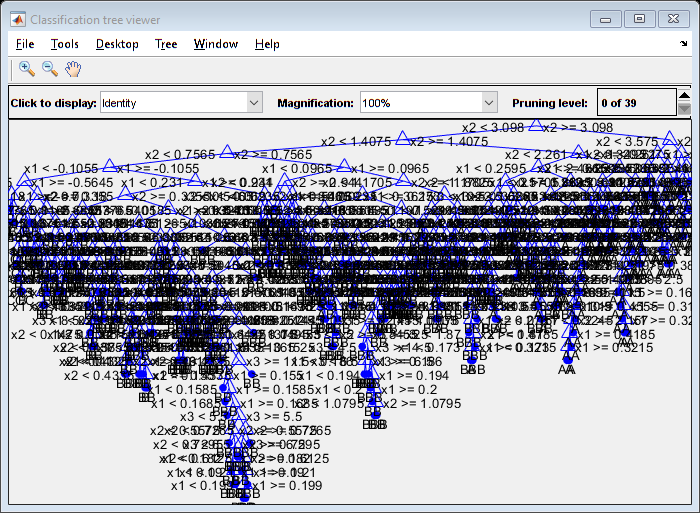

t = fitctree(FinRatios_t,Ratings_t);
view(t,'mode','graph')

Predict the credit ratings for the validation data and determine the validation error.

Ratings_Estimated = predict(t,FinRatios_v);
misclass = loss(t,FinRatios_v,Ratings_v);
disp(['Validation error for single tree: ',num2str(misclass)])

Validation error for single tree: 0.30793


## 2. Add noise to tree

Add noise to each predictor variable in the validation data set. 

**Hint:** Each predictor variable *i* has an intensity, which can be determined by its standard deviation $\sigma_i$. Generate standard normal samples in a matrix with equivalent dimensions to the matrix of predictor variables. Then use `bsxfun(@times,...)` to multiply each column by 8% of its respective standard deviation ($\sigma_i$).

Generated noise = normal distribution * intensity

Find standard deviation

sd = std(FinRatios_v);
sz = size(FinRatios_v);

Noise = Random numbers from normal distribution * noise intensity

noise = bsxfun(@times,randn(sz),sd*0.08);

## 3. Predict with noisy test data

Predict ratings with the noisy validation data. How does this compare with the original model?

Ratings_Estimated2 = predict(t,FinRatios_v+noise);

Determine validation error

misclass2 = loss(t,FinRatios_v+noise,Ratings_v);
disp(['Validation error for noisy data: ',num2str(misclass2)])

Validation error for noisy data: 0.32829


## 4. Fit ensemble of trees

Create an ensemble of 100 classification trees with the original data.

tb = fitcensemble(FinRatios_t,Ratings_t,'Method','Bag','Learners','tree');

## 5. Predict with noisy data

Predict the credit ratings with the noisy validation data.

Ratings_Estimated3 = predict(tb,FinRatios_v+noise);

Determine validation error.

misclass3 = loss(tb,FinRatios_v+noise,Ratings_v);
disp(['Validation error for for ensemble: ',num2str(misclass3)])

Validation error for for ensemble: 0.30026


## 6. Evaluate classification

Evaluate the classification by constructing a confusion matrix and visualize the groupings.

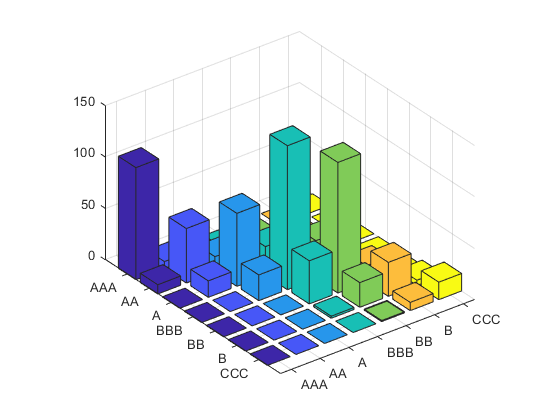

[c,lbls] = confusionmat(Ratings_v,categorical(Ratings_Estimated3));

figure
bar3(c)
ax = gca;
ax.XTickLabel = categories(lbls);
ax.YTickLabel = categories(lbls);

Create heatmap

figure
imagesc(c)

Add labels showing values in the center of heatmap

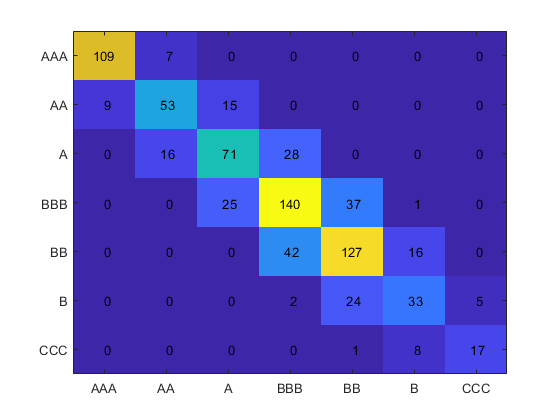

[xpos,ypos] = meshgrid(1:size(c,1),1:size(c,2));
text(xpos(:),ypos(:),num2str(c(:),'%d'),'HorizontalAlignment','Center')
ax = gca;
ax.XTickLabel = categories(lbls);
ax.YTickLabel = categories(lbls);